# **问题4：磨损情况与现有信息是否相符 ** 

在这里，为了更好地预测，并靠虑到了长时间使用中，材料发生了缓慢的改变，这种非线性的改变通过$t^{\beta}$体现

***to ljy:希望能改变Q——avg值（一个选1000，一个选5000），然后得到两组图进行对比。***

clear;clc;
% 设置随机种子
rng(42);
load F.mat;
load P.mat;
% 参数设置
L1 = 1.5; % 单位：m
L2 = 0.40; % 单位：m
m = 120; % 网格大小
n = 32; % 网格大小
T = 120;% 120月
delta_L = L1/m;
delta_S = delta_L*delta_L;
ratio= 1.0;% 上行:下行比例因子

我们通过daily patterns和uasge，可以确定阶梯的人流量矩阵Q，这屋里为例简化分析，假设Q符合均匀分布。且不失一般性地，假定上行人数：下行人数=1.2.

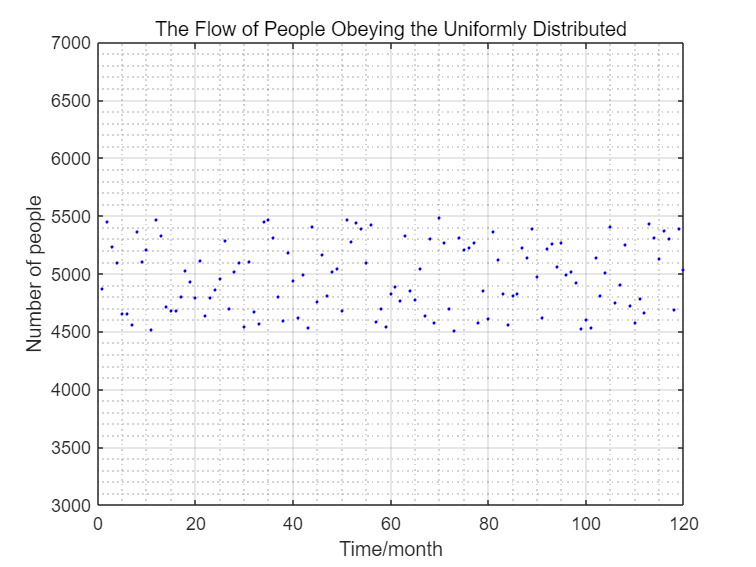

% 随机生成Q
Q_avg=500:500:10000;

[Q,Q1,Q2]=Q_production(Q_avg(10)*9/10,Q_avg(10)*11/10,1.2,T);
figure();
% 绘制点
plot(1:T, Q, 'b.', 'MarkerSize', 5, 'LineWidth', 2); % 蓝色圆点
% 配置图形
xlabel('Time/month');
ylabel('Number of people');
ylim([Q_avg(10)*6/10,Q_avg(10)*14/10]);
title('The Flow of People Obeying the Uniformly Distributed');
grid on;grid minor;

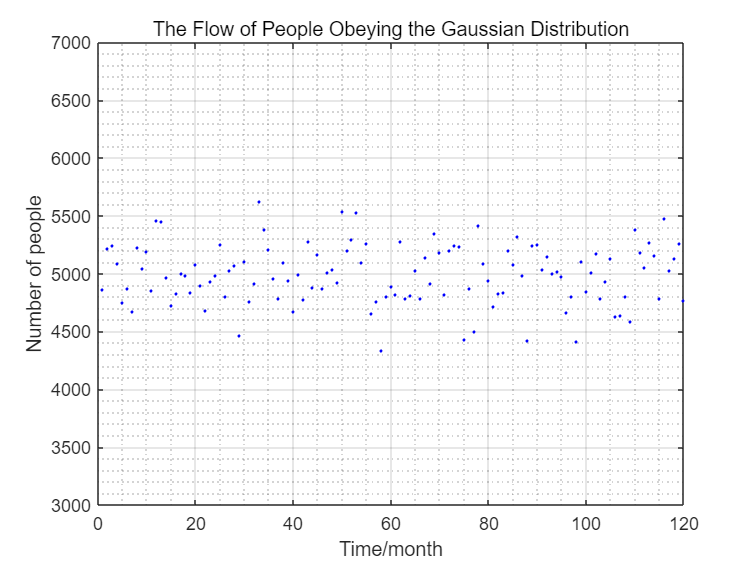


[Q,Q1,Q2]=Q_Gaussian(Q_avg(10)*9/10,Q_avg(10)*11/10,1.2,T);
figure();
% 绘制点
plot(1:T, Q, 'b.', 'MarkerSize', 5, 'LineWidth', 2); % 蓝色圆点
% 配置图形
xlabel('Time/month');
ylabel('Number of people');
ylim([Q_avg(10)*6/10,Q_avg(10)*14/10]);
title('The Flow of People Obeying the Gaussian Distribution');
grid on;grid minor;

由P.mlx，可以确定踩踏中心点的概率分布矩阵（元素可能会是小数），直接将人流量乘以概率分布矩阵，然后将其代入模型计算磨损深度分布，具体可见函数d_calculate。

这里的概况分布均为高斯分布，但是认为地规定上行靠右，下行靠左，（y轴上中心一致），便于更好地观察。

% 求d_theo
[d_theo,U_1L]=d_calculate(m,n,T,delta_S,Q1,Q2);
% 模拟d_act
[d_act,iteration]=d_actual(m,n,delta_S,Q1,Q2);
iteration

iteration = 599190

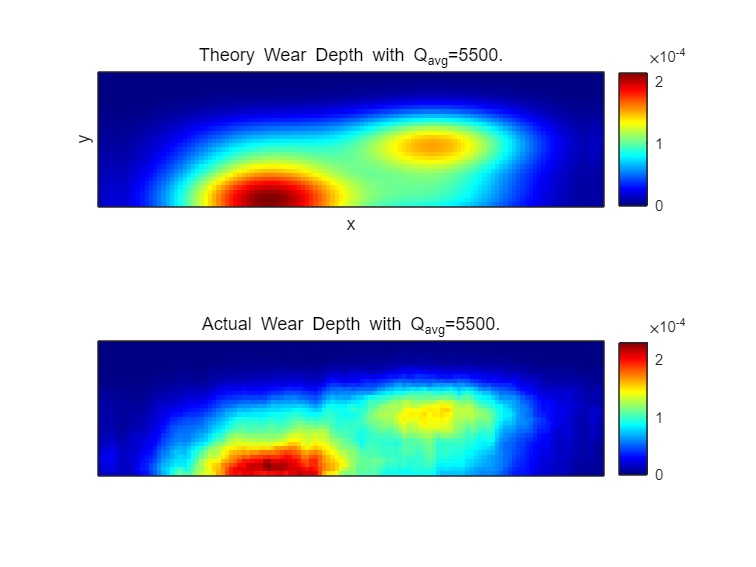

figure();
subplot(2,1,1);
imagesc(d_theo);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
title("Theory Wear Depth with Q_{avg}=5500.");
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel('x'); ylabel('y');            % 清空轴标签
subplot(2,1,2);
imagesc(d_act);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
title("Actual Wear Depth with Q_{avg}=5500.");

直接生成sum（Q）个随机点（具体数量即为iteration），将这些随机点直接代入模型计算磨损深度分布。很显然，点越多，得到的结果越精确。

分析误差矩阵的分布

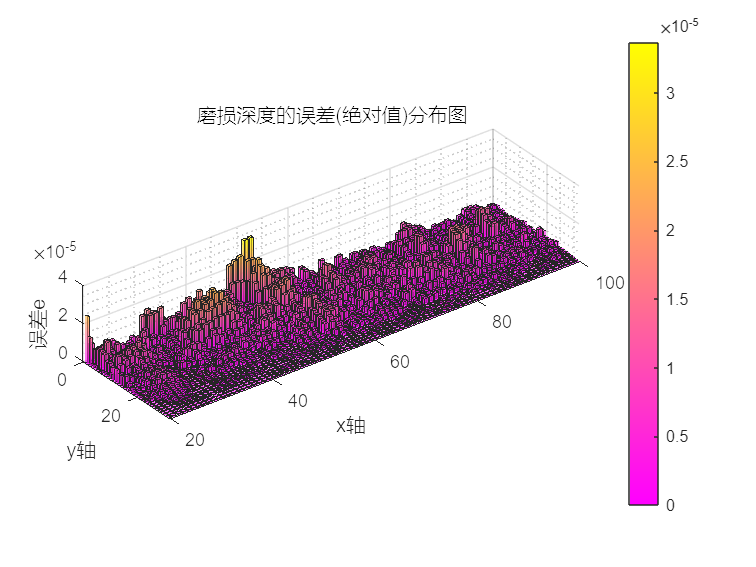

% 误差矩阵
e=abs(d_act-d_theo);
temp=e;
for i=1:n
    e(i,:)=temp(33-i,:);
end
figure();
b = bar3(e);
colorbar
%对每个曲面对象，从 ZData 属性取得 z 坐标数组。使用该数组设置 CData 属性，该属性用于定义顶点颜色。通过将曲面对象的 FaceColor 属性设置为 'interp' 来插入面颜色。使用圆点表示法查询和设置属性。
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
    b(k).FaceAlpha = 0.6; % 设置透明度，值范围 [0, 1]
end
grid on;grid minor;
colormap('spring');    % 粉红到黄色
xlabel('x轴');
ylabel('y轴');
zlabel('误差e');
title('磨损深度的误差(绝对值)分布图')
xlim([20 100])
ylim([0.0 32.0])

% 归一化误差
e_norm=(sum(sum( abs(e) )))/(sum(sum(d_theo)));
disp(e_norm);

    0.0577



有些情况下，为了节省成本或者技术、环境的限制，可能会使用对某些点进行采样分析，如下：

选取一定分布的点列进行采样，将采样结果的理论值和实际值对比。

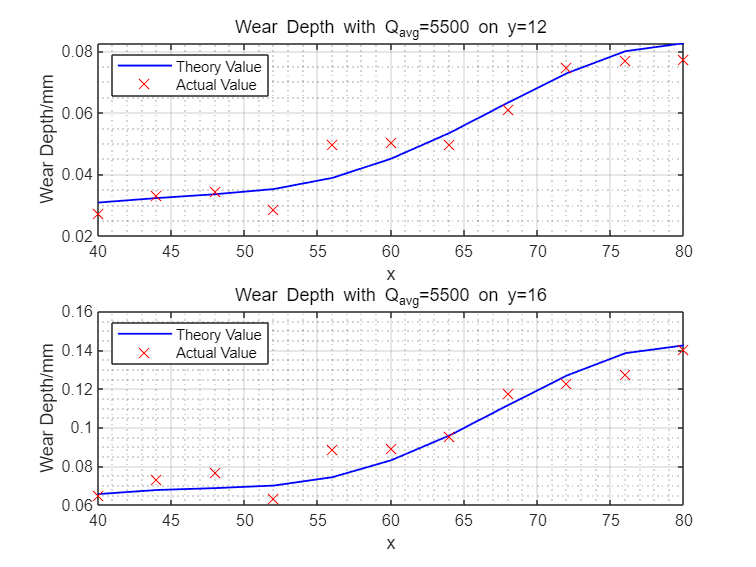

[w_theo,w_act]=sample(d_theo,d_act);

figure();
subplot(2,1,1);
plot(40:4:80, w_theo(3,:)*1000, 'b', 'LineWidth', 1);
hold on;
plot(40:4:80, w_act(3,:)*1000, 'rx', 'MarkerSize', 8);
xlabel('x');
ylabel('Wear Depth/mm');
lgd=legend("Theory Value","Actual Value");
lgd.Location="northwest";
title('Wear Depth with Q_{avg}=5500 on y=12');
grid on;grid minor;

subplot(2,1,2);
plot(40:4:80, w_theo(4,:)*1000, 'b', 'LineWidth', 1);
hold on;
plot(40:4:80, w_act(4,:)*1000, 'rx', 'MarkerSize', 8);
xlabel('x');
ylabel('Wear Depth/mm');
lgd=legend("Theory Value","Actual Value");
lgd.Location="northwest";
title('Wear Depth with Q_{avg}=5500 on y=16');
grid on;grid minor;

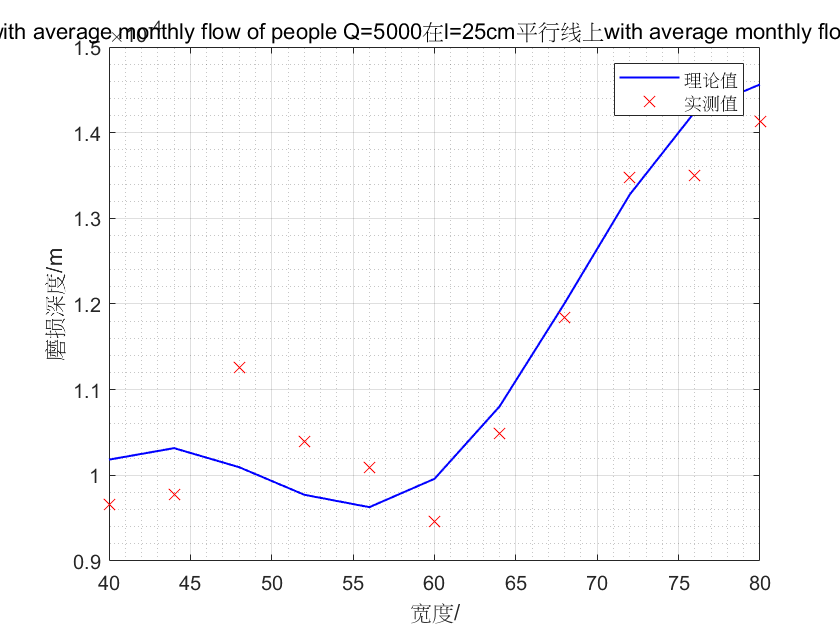


figure();
plot(40:4:80, w_theo(5,:), 'b', 'LineWidth', 1);
hold on;
plot(40:4:80, w_act(5,:), 'rx', 'MarkerSize', 8);
xlabel('宽度/');
ylabel('磨损深度/m');
legend("理论值","实测值");
title(sprintf('在l=25cm平行线上with average monthly flow of people Q=%d',Q_avg));
grid on;grid minor;

作出的误差矩阵，并进行归一化，对结果进行分析——如果归一化误差低于阈值，则认为一致，否则便不一致。

***这里的图不完善，你回头完善一下。***

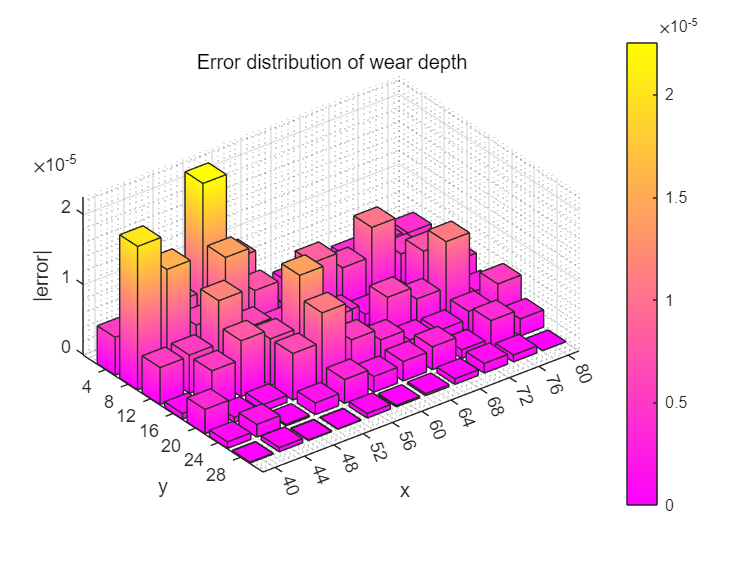

% 误差矩阵
e=abs(w_theo-w_act);
temp=e;
for i=1:7
    e(i,:)=temp(8-i,:);
end
figure();
b = bar3(e);
colorbar
%对每个曲面对象，从 ZData 属性取得 z 坐标数组。使用该数组设置 CData 属性，该属性用于定义顶点颜色。通过将曲面对象的 FaceColor 属性设置为 'interp' 来插入面颜色。使用圆点表示法查询和设置属性。
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end
grid on;grid minor;
colormap('spring');    % 粉红到黄色
xlabel('x');
ylabel('y');
zlabel('y');
zlabel('|error|');
% 自定义 X 轴和 Y 轴刻度和标签
xticks(1:11); % 设置 X 轴刻度
xticklabels({'40', '44', '48', '52', '56', '60', '64', '68', '72', '76','80'}); % X 轴标签
yticks(1:7); % 设置 Y 轴刻度
yticklabels({'4', '8', '12', '16', '20', '24', '28'}); % Y 轴标签
title('Error distribution of wear depth')

% 归一化误差
e_norm=(sum(sum(e)))/(sum(sum(w_theo)));
disp(e_norm);

    0.0605



需要注意的是归一化误差与平均流量有密切的关系，现在探究归一化误差与流量的关系。

这一段是计算不同平均人流量下的E_norm。

% E_norm=zeros(length(Q_avg),1);
% for i=1:length(Q_avg)
%     [Q,Q1,Q2]=Q_Gaussian(Q_avg(i)*9/10,Q_avg(i)*11/10,1.2,T);
%     [d_theo,temp]=d_calculate(m,n,T,delta_S,Q1,Q2);
%     [d_act,iteration]=d_actual(m,n,delta_S,Q1,Q2);
%     [w_theo,w_act]=sample(d_theo,d_act);
%     e=abs(w_act-w_theo);
%     E_norm(i)=(sum(sum(e)))/(sum(sum(w_theo)));
%     i
% end
% save('E_norm_Gaussian.mat',"E_norm",'-mat');

粗略看看变化规律

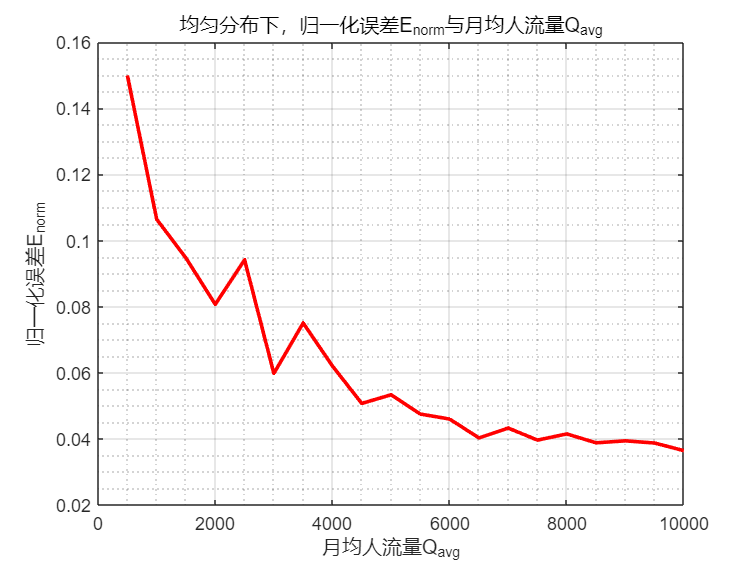

% 均匀分布
load EE_norm_uni.mat;
E_norm_uni=E_norm;
figure();
plot(Q_avg, E_norm_uni, 'r', 'LineWidth', 2);
hold on;
xlabel('月均人流量Q_{avg}');
ylabel('归一化误差E_{norm}');
%legend("理论值","实测值");
title('均匀分布下，归一化误差E_{norm}与月均人流量Q_{avg}');
grid on;grid minor;

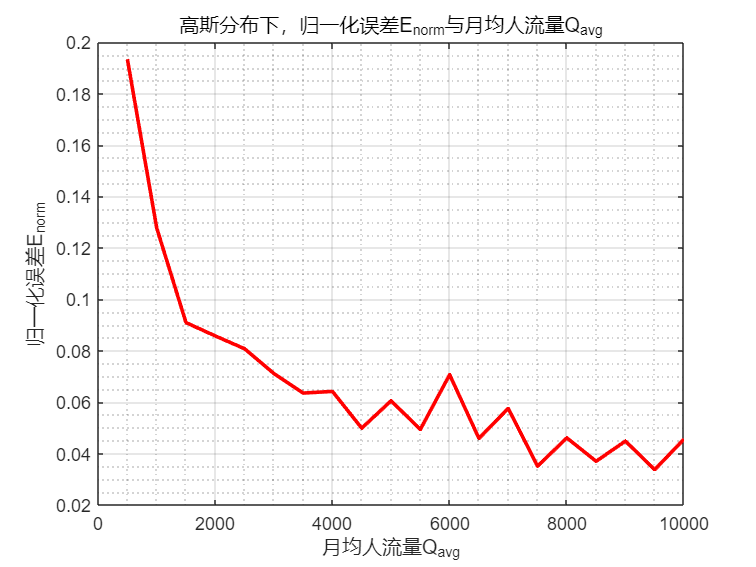

% 高斯分布
load EE_norm_Gaussian.mat;
E_norm_Gaussian=E_norm;
figure();
plot(Q_avg, E_norm_Gaussian, 'r', 'LineWidth', 2);
hold on;
xlabel('月均人流量Q_{avg}');
ylabel('归一化误差E_{norm}');
%legend("理论值","实测值");
title('高斯分布下，归一化误差E_{norm}与月均人流量Q_{avg}');
grid on;grid minor;

显然，符合对数规律，我们对其进行拟合，以确定合适的阈值。

ln_x = log(Q_avg); % 计算 x 的自然对数

% 均匀分布
% 使用 polyfit 进行线性回归
coeffs = polyfit(ln_x, E_norm_uni, 1); % 一次多项式拟合
a = coeffs(1); % 斜率
b = coeffs(2); % 截距
% 显示拟合结果
fprintf('拟合方程为: E_{norm} = %.4f * ln(Q_{avg}) + %.4f\n', a, b);

拟合方程为: E_{norm} = -0.0358 * ln(Q_{avg}) + 0.3599


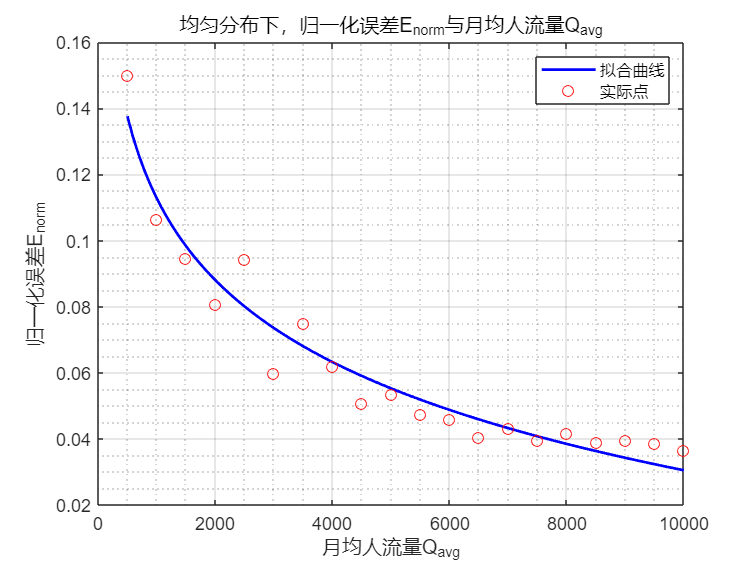

figure();
% 绘制拟合曲线
Q_avg_fit = linspace(min(Q_avg), max(Q_avg), 100); % 更细的 Q_avg 范围
E_norm_fit = a * log(Q_avg_fit) + b; % 拟合曲线
plot(Q_avg_fit, E_norm_fit, 'b-', 'LineWidth', 1.5, 'DisplayName', '拟合曲线');
hold on;
plot(Q_avg, E_norm_uni, 'ro', 'MarkerSize', 6);
grid on;grid minor;
xlabel('月均人流量Q_{avg}');
ylabel('归一化误差E_{norm}');
legend('拟合曲线','实际点');
title('均匀分布下，归一化误差E_{norm}与月均人流量Q_{avg}');


% 高斯分布
% 使用 polyfit 进行线性回归
coeffs = polyfit(ln_x, E_norm_Gaussian, 1); % 一次多项式拟合
a = coeffs(1); % 斜率
b = coeffs(2); % 截距
% 显示拟合结果
fprintf('拟合方程为: E_{norm} = %.4f * ln(Q_{avg}) + %.4f\n', a, b);

拟合方程为: E_{norm} = -0.0429 * ln(Q_{avg}) + 0.4249


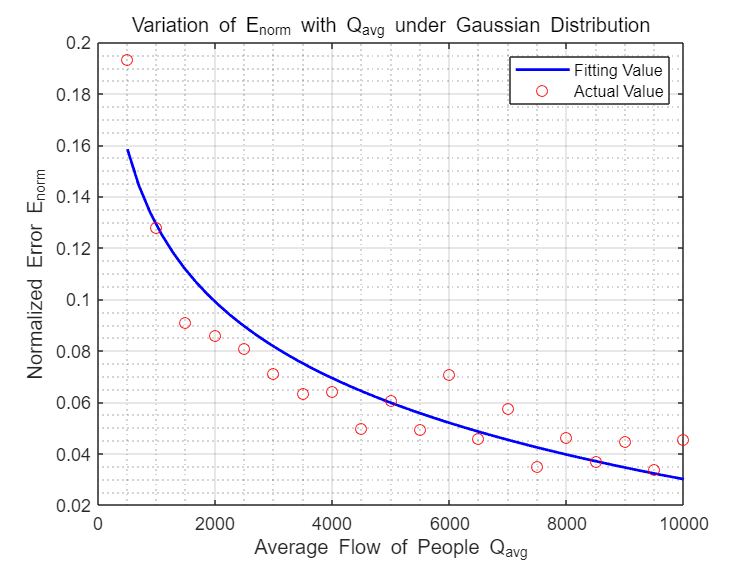

f1=figure();
% 绘制拟合曲线
Q_avg_fit = linspace(min(Q_avg), max(Q_avg), 50); % 更细的 Q_avg 范围
E_norm_fit = a * log(Q_avg_fit) + b; % 拟合曲线
plot(Q_avg_fit, E_norm_fit, 'b-', 'LineWidth', 1.5, 'DisplayName', '拟合曲线');
hold on;
plot(Q_avg, E_norm_Gaussian, 'ro', 'MarkerSize', 6);
grid on;grid minor;
xlabel('Average Flow of People Q_{avg}');
ylabel('Normalized Error E_{norm}');
legend('Fitting Value','Actual Value');
title('Variation of E_{norm} with Q_{avg} under Gaussian Distribution');

在拟合的基础上再留有一定余裕，即可得到合理的阈值。

function [w_theo,w_act]=sample(d_theo,d_act)
% 选取固定点列进行抽样
N=7;
M=11;
w_theo=zeros(N,M);
w_act=zeros(N,M);
for i=1:N
    for j=1:M
        w_theo(i,j)=d_theo(i*4,36+j*4);
        w_act(i,j)=d_act(i*4,36+j*4);
    end
end
end